Description:

This livescript contains the code and the output results for the PI controller that controls the speed of a work table. 

Root Locus analysis for the open loop transfer function:

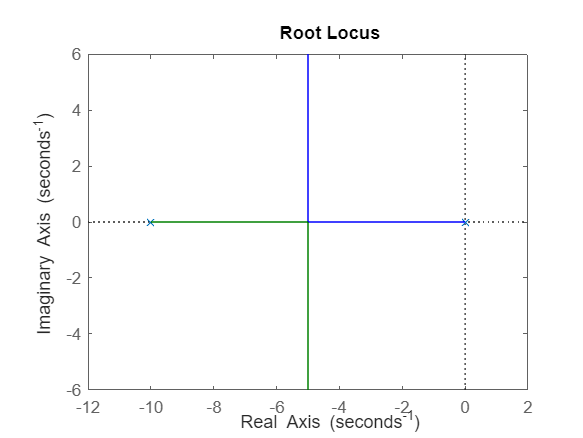

% Open loop transfer function
A_s = tf([25],[1 10 0]);
rlocus(A_s);

Step response for the closed loop transfer function, after the calculation of the gain:

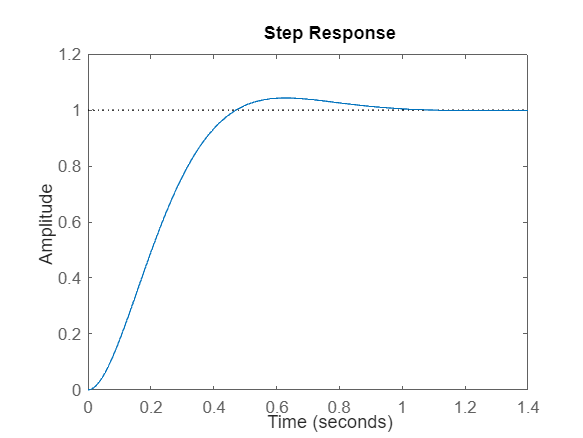

% Open loop transfer function for kp = 2
A_s = tf([50],[1 10 0]);

% Closed loop transfer function for kp = 2
H_s = feedback(A_s, 1, -1);

% Step response for the closed loop transfer function
figure;
step(H_s);


% Info about the step response
S = stepinfo(H_s);

% Print the results about rise time and overshoot 
fprintf('STEP RESPONSE RESULTS');

STEP RESPONSE RESULTS

fprintf('Rise time(sec): %f', S.RiseTime);

Rise time(sec): 0.303899

fprintf('Overshoot(%%): %f', S.Overshoot);

Overshoot(%): 4.320950